Ogólny schemat rozwiązywania zagadnień na położenie, prędkości i przyspieszenia :

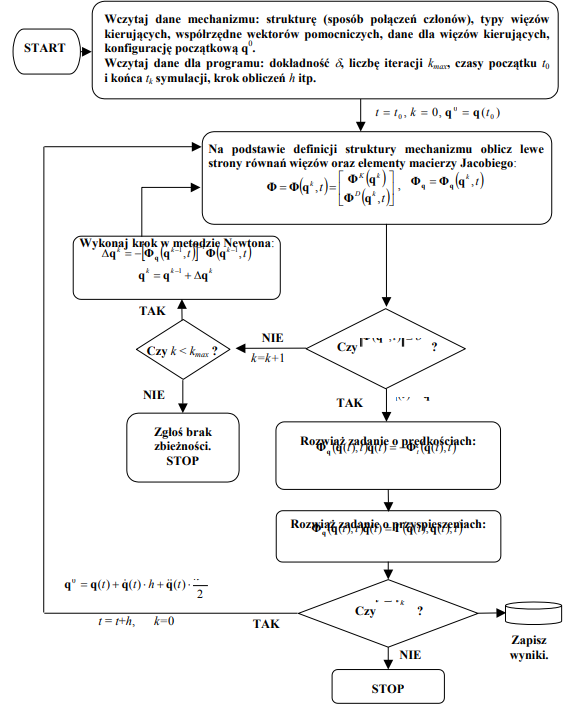

Rozwiązywanie zagadnień na przemieszczenia, prędkości i przyspieszenia można podzielić na następujące etapy:

- Wczytanie do programu informacji na temat rozwiązywanego zagadanienia, to jest: ilości członów, tworzonych przez nie par kinematycznych, jakie są wymiary analizowanego mechanizmu, zadanie więzów kierujących oraz określenie czasu symulacji oraz kroku czasowego/ilości iteracji obliczeń

- Rozwiązanie zagadnienia o położeniach, co można rozbić na etapy: wyznaczenie wektora współrzędnych absolutnych **q **spełniającego równania więzów kinematycznych i kierujących**, **rozwiązanie układu równań nieliniowych metodą Newtona-Raphsona , w tym celu konieczne jest wyznaczenie macierzy Jacobiego równań więzów. Rozwiązywanie równań linowych może zostać wykonane na przykład metodą Gaussa.

- Na podstawie wartości wyliczonych w zagadnieniu położeń obliczenie są zagadnienia na prędkości i przyspieszenia (rozwiązanie układów równań 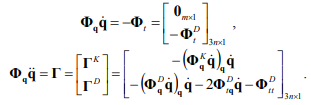 ), zagadnienia te ponownie wymagają obliczenia macierzy Jacobiego równań węzów, do obliczania układów równań liniowych wykorzystuje się metodę Gaussa.

- Po obliczeniu 3 zagadnień kinematyki obliczana, wszystkie obliczenia powtarzane są dla następnego kroku czasowego. Jako wartość przybliżenia startowego w następnym kroku czasowym można przyjąć wartosć 

- Rozwiązanie zadania kończy się w momencie osiągnięcia zdefiniowanego na początku działania programu czasu symulacji

% ======= Start.m (kod wykonywalny) =======
fprintf('Krok czasowy:\n')

Krok czasowy:


DT = 0.1

DT = 0.1000

fprintf('Czas symulacji [s]:\n')

Czas symulacji [s]:


T_MAX = 30

T_MAX = 30

[T,Q, DQ, DDQ] = Main(DT,T_MAX);

Czlony:
         0    0.8500         0    0.4000    0.7500         0    0.1500    0.4500         0    0.0500    0.1500         0    0.4500    0.6000         0    0.3500    0.2000         0    0.4000    0.1000         0    0.6500    0.2500         0    1.0500    0.3000         0    1.2000   -0.2500         0

Pary obrotowe
         0    4.0000         0         0   -0.0500   -0.1500
         0    6.0000    0.3000         0   -0.0500   -0.2000
    3.0000    1.0000    0.0500    0.1500    0.2000   -0.2500
         0    1.0000   -0.1000    0.7000   -0.1000   -0.1500
    1.0000    7.0000   -0.2000   -0.0500   -0.6000    0.7000
    1.0000    2.0000         0    0.3500   -0.4000    0.4500
    2.0000    5.0000    0.1000    0.0500    0.0500    0.2000
    7.0000    8.0000    0.1000   -0.2000   -0.1500   -0.3500
    2.0000    8.0000    0.3000   -0.4500    0.0500    0.0500
    8.0000    9.0000    0.1500    0.3500   -0.2500    0.3000
    7.0000   10.0000    0.6000   -0.6000   -0.2000   -0.2500
    9

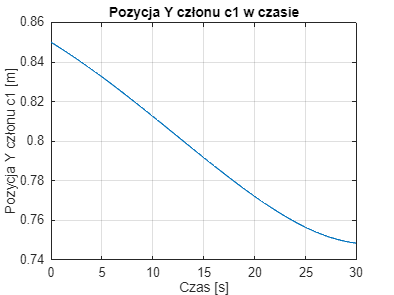

plot(T, Q(2, :))
xlabel('Czas [s]')
ylabel('Pozycja Y członu c1 [m]')
title('Pozycja Y członu c1 w czasie')
grid on

%plot(T,Q(n,:))

% czlon a
% a(x) - n=3*a-2
% a(y) - n=3*a-1
% a(fi) - n=3*a
%-----------------------------------------------------------------------

**Rotacja**

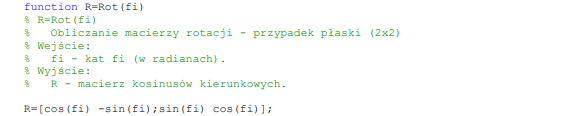


function R = Rot(fi)
%Macierz rotacji dla przypadku 2D - k¹t fi wyra¿ony w radianach
R = [cos(fi) -sin(fi); sin(fi) cos(fi)];  
end

% ======= Main.m =======
function [T,Q, DQ, DDQ] = Main(DT,T_MAX)
    
    %Pobranie danych z plików txt
    [Czlony, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe] = Dane();
    
    % Przybliżenie startowe  
    Q_TEMP = Czlony;
    DQ_TEMP = zeros(length(Q_TEMP),1); 
    DDQ_TEMP = zeros(length(Q_TEMP),1);  
    
    %Wyznaczenie liczby wyników i zadeklarowanie licznika 
    IleIteracji = 1;
    Size = T_MAX/DT + 1;
    
    %Zadeklarowanie rozmiaru macierzy i wektorów gromadzących wyniki
    T = zeros(1, Size);
    Q = zeros(length(Q_TEMP), Size);
    DQ = zeros(length(Q_TEMP), Size);
    DDQ = zeros(length(Q_TEMP), Size);

    %Rozwiązywanie zadań kinematyki w kolejnych chwilach T_TEMP
    for T_TEMP = 0:DT:T_MAX
        Q_TEMP=Q_TEMP+DQ_TEMP*DT+0.5*DDQ_TEMP*DT*DT;
        
        %Rozwiązanie zadania o położenie
        Q_TEMP=NewRaph(Q_TEMP, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe, T_TEMP); 
        
        %Rozwiązanie zadania o prędkości
        DQ_TEMP=Predkosc(Q_TEMP, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe,T_TEMP); 
        
        %Rozwiązanie zadania o przyśpieszenia 
        DDQ_TEMP=Przyspieszenie(DQ_TEMP,Q_TEMP, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe,T_TEMP);

        %Zapisane wyników do macierzy i wektorów gromadzących
        T(1,IleIteracji) = T_TEMP; 
        Q(:,IleIteracji) = Q_TEMP;
        DQ(:,IleIteracji) = DQ_TEMP;
        DDQ(:,IleIteracji) = DDQ_TEMP;
    
        IleIteracji = IleIteracji + 1;
    end
end

Definicja funkcji obliczającej pochodne wymuszeń postępowcyh. Zakładana jest postać wymuszenia postępowego  

function [ x ] = WymuszenieP( indeks, pochodna, t,ParyPostepowe, WymPostepowe )
    %Zwraca dla danego czasu wartość danej pochodnej wybranego wymuszenia postępowego
    
    
     L=sqrt((ParyPostepowe(indeks,10)-ParyPostepowe(indeks,12))^2+(ParyPostepowe(indeks,11)-ParyPostepowe(indeks,13))^2)+WymPostepowe(indeks,3); %początkowa długość l_k wynika z odległości pomiędzy punktami tworzącymi kinematyczną parę postępową. Do wartości tej dodawana jest zczytywana z pliku wartość wychylenia początkowego
     A=WymPostepowe(indeks,4);
     OM=WymPostepowe(indeks,5);
     FI=WymPostepowe(indeks,6);

    if(pochodna == 0)
    
            x = L + A*sin(OM*t + FI);
            
       
    elseif(pochodna == 1)
        
             x = A*OM*cos(OM*t + FI);
               
    elseif(pochodna == 2)
             
             x = -A*OM*OM*sin(OM*t + FI);
                
 
    else
        disp('Nieprawidłowy indeks pochodnej')
    end


end


Wczytanie danych do programu. Format danych: 

**Dla członów:**

Pierwszy wiersz - ilość członów w analizowanym mechanizmie

Kolejne wiersze - współrzędne środków ciężkości członów

*człon o numerze 0 jest zawsze przyjmowany jako podłoże

**Dla par kinematycznych:**

Pierwszy wiersz - ilość par obrotowych (i)

Wiersze 2:i+1 - numery członów wchodzących w skład pary kinematycznej,    współrzędne pary kinematycznej

Wiersz i+2 - ilość par postępowych (j)

Wiersze i+3:i+j+3 - numery członów wchodzących w skład pary kinematycznej,    współrzędne pary kinematycznej

**Wymuszenia**

Pierwszy wiersz - ilość wymuszeń obrotowych (i)

Wiersze 2:i+1 - parametry równania opisujące wymuszenie obrotowe

Wiersz i+2 - ilość wymuszeń postępowych (j)

Wiersze i+3:i+j+3 - Parametry opisujące wymuszenia postępowe

W zadaniu przyjmuje się, że równanie opisujące wymuszenie postępowa ma postać  , kolejność występowania parametrów w równaniu jest taka sama jak kolejność danych w pliku wsadowym

% ======= Dane.m =======
function [Czlony, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe] = Dane()
    %Funkcja wczytująca dane z plików txt 
    
    c = fopen('Dane/Człony.txt', 'r');
    p = fopen('Dane/Pary.txt', 'r');
    w = fopen('Dane/Wymuszenia.txt', 'r');
    
    %Wczytanie członów
    no = str2num(fgetl(c));  % wczytanie liczby członów
    for i = 1:no
        Czlony(3*(i-1)+1:3*i) = str2num(fgetl(c));  %wczytanie poszczególnych członów [x,y,fi]
    end
    fprintf('Czlony:\n')
    disp(Czlony)
    Czlony = Czlony'; %macierz 3 x no
    
    %Wczytanie par obrotowych - rozdzial 2.3
    no = str2num(fgetl(p));     %liczba par obrotowych
    ParyObrotowe = zeros(no, 6); %stworzenie pustej początkowej macierzy przechowywującej pary obrotowe
    for i = 1:no %przepisanie wartości z pliku wsadowego do kompilatora
        tmp = str2num(fgetl(p));
        Czlon1 = tmp(1); Czlon2 = tmp(2);
        Polozenie = [tmp(3); tmp(4)];

        if(Czlon1==0) %sprawdzenie warunku podłoża
            q1 = [0;0]; f1 = 0;
        else
            q1 = Czlony(3*Czlon1-2 : 3*Czlon1-1); f1 = Czlony(3*Czlon1);
        end
        
        if(Czlon2==0)%sprawdzenie warunku podłoża
            q2 = [0;0]; f2 = 0;
        else
            q2 = Czlony(3*Czlon2-2 : 3*Czlon2-1); f2 = Czlony(3*Czlon2);
        end
        
        R1 = Rot(f1); 
        R2 = Rot(f2);

        ParyObrotowe(i,1:2) = [Czlon1,Czlon2]; %definicja wektora par obrotowych
        ParyObrotowe(i,3:4) = R1'*(Polozenie-q1);
        ParyObrotowe(i,5:6) = R2'*(Polozenie-q2);
        
    end
    fprintf('Pary obrotowe\n')
    disp(ParyObrotowe)
    %Wczytanie par postępowych - rozdział 2.3, postępowanie analogiczne do par obrotowych
    no = str2num(fgetl(p));
    ParyPostepowe = zeros(no,13);
    for i = 1:no
        tmp = str2num(fgetl(p));
        Czlon1 = tmp(1); Czlon2 = tmp(2);
        Polozenie1 = [tmp(3); tmp(4)];
        Polozenie2 = [tmp(5); tmp(6)];

        if(Czlon1==0)
            q1 = [0;0]; f1 = 0;
        else
            q1 = Czlony(3*Czlon1-2 : 3*Czlon1-1); f1 = Czlony(3*Czlon1);
        end
        
        if(Czlon2==0)
            q2 = [0;0]; f2 = 0;
        else
            q2 = Czlony(3*Czlon2-2 : 3*Czlon2-1); f2 = Czlony(3*Czlon2);
        end

    R1 = Rot(f1); R2 = Rot(f2);
    ParyPostepowe(i,1:2) = [Czlon1,Czlon2];
    ParyPostepowe(i,3) = f1 - f2;
    ParyPostepowe(i,6:7) = R1'*(Polozenie1-q1);
    ParyPostepowe(i,8:9) = R2'*(Polozenie2-q2);
    ParyPostepowe(i,10:13)=[Polozenie1',Polozenie2'];
    U = [Polozenie2(1)-Polozenie1(1);Polozenie2(2)-Polozenie1(2)];
    U = U/norm(U);
    U = R2'*U;
    ParyPostepowe(i,4:5) = U';
    end
    fprintf('Pary Postępowe:\n')
    disp(ParyPostepowe)
    %Wczytanie wymuszen obrotowych 
    no = str2num(fgetl(w));
    WymObrotowe = zeros(no,2);
    for i  = 1:no
        WymObrotowe(i,:) = str2num(fgetl(w));
    end
    fprintf('Wymuszenia Obrotowe:\n')
    disp(WymObrotowe)
    %Wczytanie wymuszen postepowych 
    no = str2num(fgetl(w));


    WymPostepowe = zeros(no,6);
    for i  = 1:no
        WymPostepowe(i,:) = str2num(fgetl(w));
        
    end
    fprintf('Wymuszenia postępowe:\n')
    disp(WymPostepowe)
end
        


Funkcja realizująca metodę Newtona-Raphsona


% ======= NewRaph.m =======
function Q_TEMP = NewRaph(Q_TEMP, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe, T_TEMP)
    %Rozwiązanie układu równań metodą Newtona-Raphsona

    F = ones(length(Q_TEMP),1);
    EPS = 10e-9;
    IleIteracji = 1;
    MaxIteracji = 25;

    while(norm(F) > EPS && IleIteracji < MaxIteracji)
        F = Wiezy(Q_TEMP, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe, T_TEMP);
        FQ = Jakobian(Q_TEMP, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe);
        Q_TEMP = Q_TEMP - FQ\F;
        IleIteracji = IleIteracji + 1;
    end
    
    
    if(IleIteracji > MaxIteracji)
        disp('Nie udało się uzyskać zbieżności po założonej liczbie iteracji')
    end
end



Funkcja licząca zagadnienie prędkości 

% ======= Predkosc.m =======
function [DQ] = Predkosc(Q_TEMP, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe,T_TEMP)
    %Funkcja rozwiązująca zadanie o prędkości
    
    FT = zeros(length(Q_TEMP), 1);
    Pozycja = 2*(size(ParyObrotowe, 1) + size(ParyPostepowe, 1))+1;

    %Tutaj wstawiłbym wymuszenia obrotowe, ale ich nie ma
    
    %Wymuszenia postępowe
    for i=1:size(WymPostepowe,1)
        FT(Pozycja, 1) = -1*WymuszenieP(WymPostepowe(i, 2), 1, T_TEMP,ParyPostepowe, WymPostepowe);
        Pozycja = Pozycja + 1;
    end

    FQ = Jakobian(Q_TEMP, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe);
    DQ = -FQ \ FT;

    end

Funkcja licząca zagadnienie przyspieszeń



% ======= Przyspieszenie.m =======
function [DDQ] = Przyspieszenie(DQ_TEMP,Q_TEMP, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe,T_TEMP)
    %Funkcja wyznaczająca przyśpieszenie

    Om = [0 -1; 1 0]; 
    Gamma = zeros(length(Q_TEMP), 1);
    Pozycja = 1;
     
    %Pary obrotowe
    for i=1:size(ParyObrotowe,1) 
        P1 = ParyObrotowe(i, 1);
        P2 = ParyObrotowe(i, 2);
    
        [~,~,Rot1] = Polozenia(Q_TEMP, P1);
        [~,~,Rot2] = Polozenia(Q_TEMP, P2);
    
        sA = ParyObrotowe(i, 3:4)';
        sB = ParyObrotowe(i, 5:6)';
    
        [~,Dfi1,~]= Polozenia(DQ_TEMP,P1);
        [~,DFi2,~]= Polozenia(DQ_TEMP,P2);
        
        %Wzór 2.40 ze skryptu
        Gamma(Pozycja:Pozycja+1, 1) = Rot1 * sA * Dfi1^2 - Rot2 * sB * DFi2^2;
    
        Pozycja = Pozycja + 2;
    end
    
    %Pary postępowe
    for i=1:size(ParyPostepowe,1) 
        %Wzór 2.46 ze skryptu        
        Gamma(Pozycja, 1) = 0;
        Pozycja = Pozycja + 1;

        P1 = ParyPostepowe(i, 1);
        P2 = ParyPostepowe(i, 2);

        U = ParyPostepowe(i, 4:5)';
        V = [-U(2); U(1)];
        sA = ParyPostepowe(i, 6:7)';

        [R1,~,Rot1] = Polozenia(Q_TEMP, P1);
        [R2,~,Rot2] = Polozenia(Q_TEMP, P2);

        [DR1,Dfi1,~] = Polozenia(DQ_TEMP,P1);
        [DR2,DFi2,~] = Polozenia(DQ_TEMP,P2);

        %Wzór 2.57 ze skryptu
        Gamma(Pozycja, 1) = (Rot2 * V)'*(2 * Om * (DR2 - DR1) * DFi2 + (R2 - R1) * DFi2^2 - Rot1 * sA * (DFi2 - Dfi1)^2 ); 

        Pozycja = Pozycja + 1;
    end

    %Tu należałoby wstawić wymuszenia obrotowe

    for i=1:size(WymPostepowe,1) %petla po wszystkich wymuszeniach postepowych    
        P1 = ParyPostepowe(WymPostepowe(i, 1), 1);
        P2 = ParyPostepowe(WymPostepowe(i, 1), 2);

        U = ParyPostepowe(WymPostepowe(i, 1), 4:5)';
        sA = ParyPostepowe(WymPostepowe(i, 1), 6:7)';

        [R1,~,Rot1] = Polozenia(Q_TEMP, P1);
        [R2,~,Rot2] = Polozenia(Q_TEMP, P2);

        [DR1,Dfi1,~]=Polozenia(DQ_TEMP,P1);
        [DR2,DFi2,~]=Polozenia(DQ_TEMP,P2);

        %Wzór 2.57 ze skryptu
        Gamma(Pozycja, 1) = (Rot2 * U)'*(2 * Om * (DR2 - DR1) * DFi2 + (R2 - R1) * DFi2^2 - Rot1 * sA * (DFi2 - Dfi1)^2 ) +WymuszenieP(WymPostepowe(i, 2), 2, T_TEMP,ParyPostepowe, WymPostepowe); 

        Pozycja = Pozycja + 1;
    end

    %Obliczenie macierzy układu równań
    FQ = Jakobian(Q_TEMP, ParyObrotowe, ParyPostepowe, WymObrotowe, WymPostepowe);

    %Rozwiązanie
    DDQ = FQ \ Gamma;
end

Funkcja definiująca równania więzów 



% ======= Wiezy.m =======
function F = Wiezy(Q_TEMP, ParyObrotowe, ParyPostepowe, ~, WymPostepowe, T_TEMP)
    %Funkcja wyznaczająca wartości funkcji opisujących więzy
 
    %Zadeklarowanie wektora wyjściowego
    F = zeros(length(Q_TEMP),1);
    Pozycja = 1;

    %Stworzenie równań dla par obrotowych
    for i = 1:(size(ParyObrotowe,1))
        [R1, ~, Rot1] = Polozenia(Q_TEMP,ParyObrotowe(i,1));
        [R2, ~, Rot2] = Polozenia(Q_TEMP,ParyObrotowe(i,2));
        sA = ParyObrotowe(i,3:4)';
        sB = ParyObrotowe(i,5:6)';
 
        %Wzór 2.16 w skrypcie z wykładu
        F(Pozycja:Pozycja+1,1) = R1 + Rot1 * sA - (R2 + Rot2 * sB);
        
        Pozycja = Pozycja + 2;
    end

    %Stworzenie równań dla par postępowych 
    for i = 1:(size(ParyPostepowe,1))
        [R1, Fi1, Rot1] = Polozenia(Q_TEMP,ParyPostepowe(i,1));
        [R2, Fi2, Rot2] = Polozenia(Q_TEMP,ParyPostepowe(i,2));  
       
        Fi0 = ParyPostepowe(i,3);
        sA = ParyPostepowe(i,6:7)';
        sB = ParyPostepowe(i,8:9)';
        U = ParyPostepowe(i,4:5)';
        V = [-U(2); U(1)];

        %Wzór 2.17
        F(Pozycja,1) = Fi1 - Fi2 - Fi0;
        
        %Wzór 2.20
        F(Pozycja+1,1) = (Rot2 * V)'*(R2 - R1 - Rot1 * sA) + V' * sB;
        
        Pozycja = Pozycja + 2;
    end

    %Gdyby w zadaniu były wymuszenia obrotowe to powinien znaleźć się tu kod który by
    %coś z nimi robił, ale ich nie ma

    %Stworzenie równań dla wymuszeń postępowych
    for i = 1:(size(WymPostepowe,1))
        [R1,~,Rot1] = Polozenia(Q_TEMP,ParyPostepowe(WymPostepowe(i,1),1));
        [R2,~,Rot2] = Polozenia(Q_TEMP,ParyPostepowe(WymPostepowe(i,1),2));
        U = ParyPostepowe(WymPostepowe(i,1),4:5)';
        sA = ParyPostepowe(WymPostepowe(i,1),6:7)';
        sB = ParyPostepowe(WymPostepowe(i,1),8:9)';
        
        % wzor 2.26 na wymuszenie w parze postepowej
        F(Pozycja,1) = (Rot2 * U)'*(R2 + Rot2 * sB - R1 - Rot1 * sA) - WymuszenieP(WymPostepowe(i,2),0,T_TEMP,ParyPostepowe, WymPostepowe);
        
        Pozycja = Pozycja + 1;
    end
end

Funkcja licząca Jakobian 

%% jakobian

function [FQ] = Jakobian(Q_TEMP, ParyObrotowe, ParyPostepowe, ~, WymPostepowe)
    %Funkcja wyznaczająca Jakobian równañ wiêzów 
    
    Om = [0 -1; 1 0];
    FQ = zeros(length(Q_TEMP),length(Q_TEMP));
    Pozycja = 1;

    %Pary obrotowe
    for i = 1:size(ParyObrotowe,1)
        sA = ParyObrotowe(i,3:4)';
        sB = ParyObrotowe(i,5:6)';
        [~,~,Rot1] = Polozenia(Q_TEMP,ParyObrotowe(i,1));
        [~,~,Rot2] = Polozenia(Q_TEMP,ParyObrotowe(i,2));
        
        %Je¿eli dany człon nie jest podstawą
        if ParyObrotowe(i,1) ~= 0 
            %Wzór 2.29 ze skryptu
            FQ(Pozycja:Pozycja+1, ParyObrotowe(i,1)*3-2:ParyObrotowe(i,1)*3-1) = eye(2);
            
            %Wzór 2.30 ze skryptu
            FQ(Pozycja:Pozycja+1,ParyObrotowe(i,1)*3) = Om * Rot1 * sA; 
        end
        
        %Je¿eli dany czlon nie jest podstawą
        if ParyObrotowe(i,2) ~= 0
            %Wzór 2.31 ze skryptu
            FQ(Pozycja:Pozycja+1, ParyObrotowe(i,2)*3-2:ParyObrotowe(i,2)*3-1) = -eye(2); 
            
            %Wzór 2.32 ze skryptu
            FQ(Pozycja:Pozycja+1, ParyObrotowe(i,2)*3) = -Om * Rot2 * sB; 
        end
    
        Pozycja = Pozycja + 2;
    end

    %Pary postepowe
    for i = 1:size(ParyPostepowe,1)
        U = ParyPostepowe(i,4:5)';
        V = [-U(2); U(1)];
        sA = ParyPostepowe(i,6:7)';
        
        [R1,~,Rot1] = Polozenia(Q_TEMP,ParyPostepowe(i,1));
        [R2,~,Rot2] = Polozenia(Q_TEMP,ParyPostepowe(i,2));
        
        %Je¿eli dany człon nie jest podstawą
        if ParyPostepowe(i,1) ~= 0
            %Wzór 2.42 ze skryptu
            FQ(Pozycja, ParyPostepowe(i,1)*3) = 1; 
            
            %Wzór 2.47 ze skryptu
            FQ(Pozycja+1, ParyPostepowe(i,1)*3-2:ParyPostepowe(i,1)*3-1) = -(Rot2 * V)'; 
            
            %Wzór 2.48 ze skryptu
            FQ(Pozycja+1, ParyPostepowe(i,1)*3) = -(Rot2 * V)' * Om * Rot1 * sA; 
        end
        
        %Je¿eli człon nie jest podstawą
        if ParyPostepowe(i,2) ~= 0
            %Wzór 2.44 ze skryptu
            FQ(Pozycja, ParyPostepowe(i,2)*3) = -1; 
            
            %Wzór 2.49 ze skryptu
            FQ(Pozycja+1, ParyPostepowe(i,2)*3-2:ParyPostepowe(i,2)*3-1) = (Rot2 * V)'; 
            
            %Wzór 2.50 ze skryptu
            FQ(Pozycja+1, ParyPostepowe(i,2)*3) = -(Rot2 * V)' * Om * (R2 - R1 - Rot1 * sA); 
        end
   
        Pozycja = Pozycja + 2;
    end

    %Gdyby byly wymuszenia obrotowe to tutaj trzeba by było coś z nimi
    %zrobić, ale ich nie ma

    %Wymuszenia postepowe
    for i = 1:size(WymPostepowe,1)
        U = ParyPostepowe(WymPostepowe(i,1),4:5)';
        sA = ParyPostepowe(WymPostepowe(i,1),6:7)';
        
        [R1,~,Rot1] = Polozenia(Q_TEMP,ParyPostepowe(WymPostepowe(i,1),1));
        [R2,~,Rot2] = Polozenia(Q_TEMP,ParyPostepowe(WymPostepowe(i,1),2));
        
        %Je¿eli cz³on nie jest podstaw¹
        if ParyPostepowe(WymPostepowe(i,1),1) ~= 0
            %Wzór 2.47 ze skryptu
            FQ(Pozycja, ParyPostepowe(WymPostepowe(i,1),1)*3-2:ParyPostepowe(WymPostepowe(i,1),1)*3-1) = -(Rot2 * U)'; 
            
            %Wzór 2.48 ze skryptu
            FQ(Pozycja, ParyPostepowe(WymPostepowe(i,1),1)*3) = -(Rot2 * U)' * Om * Rot1 * sA; % 
        end
        
        %Je¿eli człon nie jest podstawą
        if ParyPostepowe(WymPostepowe(i,1),2) ~= 0
            %Wzór 2.49 ze skryptu
            FQ(Pozycja, ParyPostepowe(WymPostepowe(i,1),2)*3-2:ParyPostepowe(WymPostepowe(i,1),2)*3-1) = (Rot2 * U)'; 
            
            %Wzór 2.50 ze skryptu
            FQ(Pozycja, ParyPostepowe(WymPostepowe(i,1),2)*3) = -(Rot2 * U)' * Om * (R2 - R1 - Rot1 * sA); 
        end
        Pozycja = Pozycja + 1;
    end
    
    %Sprawdzenie osobliwości Jakobianu
    if(det(FQ)==0)
        disp('Uwaga - Jakobian jest osobliwy')
    end
end

% 

%% polozenia

Funkcja wczytująca obecne położenia

function [R, Fi, Roti] = Polozenia(Q,indeks)
    %Funkcja pobierająca aktualne współrzędne 

    if(indeks == 0) %Dla podstawy
        R = [0;0]; Fi = 0; Roti = Rot(Fi);
    else
        R = Q(3*indeks-2:3*indeks-1);
        Fi = Q(3*indeks);
        Roti = Rot(Fi);
    end
end



